# Train Network for Green Adjustments

Load saved data

load trainHueVariance.mat
paths = T.path

paths = 4999×1 cell array
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\4466.tif'                                                                                            }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.08.18.19.14.49_3a95135f-95f9-4228-a0fe-434f2e84d3dd_IMG_20180818_190357_135069259.tif'          }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\6184.tif'                                                                                            }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.11.05.19.31.12_f9a4c220-68cf-4053-9b9f-d6e268993507_IMG_20181105_130111_1523139871024008725.tif'}
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.05.09.11.08.51_cc0c83bd-7d5d-4812-93f2-ab141b11f3e5_IMG_20180508_081330_-1107019973.tif'        }
    {'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.12.09.11.53.41_d06a5c7c-64ea-43d6-b721-3292ca1863d1_IMG_20181208_111018_135124450.tif'          }
    {'C:\Users\User\

Setup Transfer Learning

net = alexnet

net =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


layers = net.Layers

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    

Replace the last two layers

layers(end-2:end) = [];
newLayers = [fullyConnectedLayer(2,'Name','fc8');...
    regressionLayer('Name','regressionoutput')]

newLayers =   2x1 Layer array with layers:

     1   'fc8'                Fully Connected     2 fully connected layer
     2   'regressionoutput'   Regression Output   mean-squared-error


layers =[layers; newLayers]

layers =   24x1 Layer array with layers:

     1   'data'               Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'              Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'              ReLU                          ReLU
     4   'norm1'              Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'              Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'              Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'              ReLU                          ReLU
     8   'norm2'              Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'              Max 

Check Network validity

analyzeNetwork(layers)

Choose data for validation

validx = randperm(height(T), round(height(T) * 0.25))

validx =          358         595         923         695        1869          28        3024        1720        1079        3249        4437         684         529        3970        3287        2576         776        3226        3575        4104         233        2961        4538        4066        4014        2149        4775        3764        1476        3391        2643        2396        1370        2047        3009        4424        1565        2398        1390         280        3294         511          80        2543        4610        1785        2604        1520        1814        3462



validationData = T(validx,:)

validationData = 1250×3 table
                                                                              path                                                                              hueAdjustment    satAdjustment
    ________________________________________________________________________________________________________________________________________________________    _____________    _____________

    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.06.21.15.18.53_84122e54-049a-4093-8999-ba45bb1afbe3_IMG_20180621_104549_1508067585.tif'                0.076999          0.14937  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.11.27.07.52.52_82755042-306e-4461-b0c1-eecd8f528976_IMG_20181113_110455_3332753003378085636.tif'       -0.35886         -0.10604  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\6342.tif'                                       

T(validx,:) = []

T = 3749×3 table
                                                                              path                                                                              hueAdjustment    satAdjustment
    ________________________________________________________________________________________________________________________________________________________    _____________    _____________

    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.08.18.19.14.49_3a95135f-95f9-4228-a0fe-434f2e84d3dd_IMG_20180818_190357_135069259.tif'                 0.042871         0.050351  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.11.05.19.31.12_f9a4c220-68cf-4053-9b9f-d6e268993507_IMG_20181105_130111_1523139871024008725.tif'       -0.17734        0.0066817  
    'C:\Users\User\Google Drive\Greenstand\HueAdjusted\2018.12.09.11.53.41_d06a5c7c-64ea-43d6-b721-3292ca1863d1_IMG_

Set training options

opts = trainingOptions('adam', 'MaxEpochs',14,...
    'Plots','training-progress',...
'ValidationData',validationData,'ExecutionEnvironment','gpu')

opts =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 14
                 MiniBatchSize: 128
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: [1250×3 table]
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'gpu'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress'
                SequenceLength: 'longest'
     

Perform Training

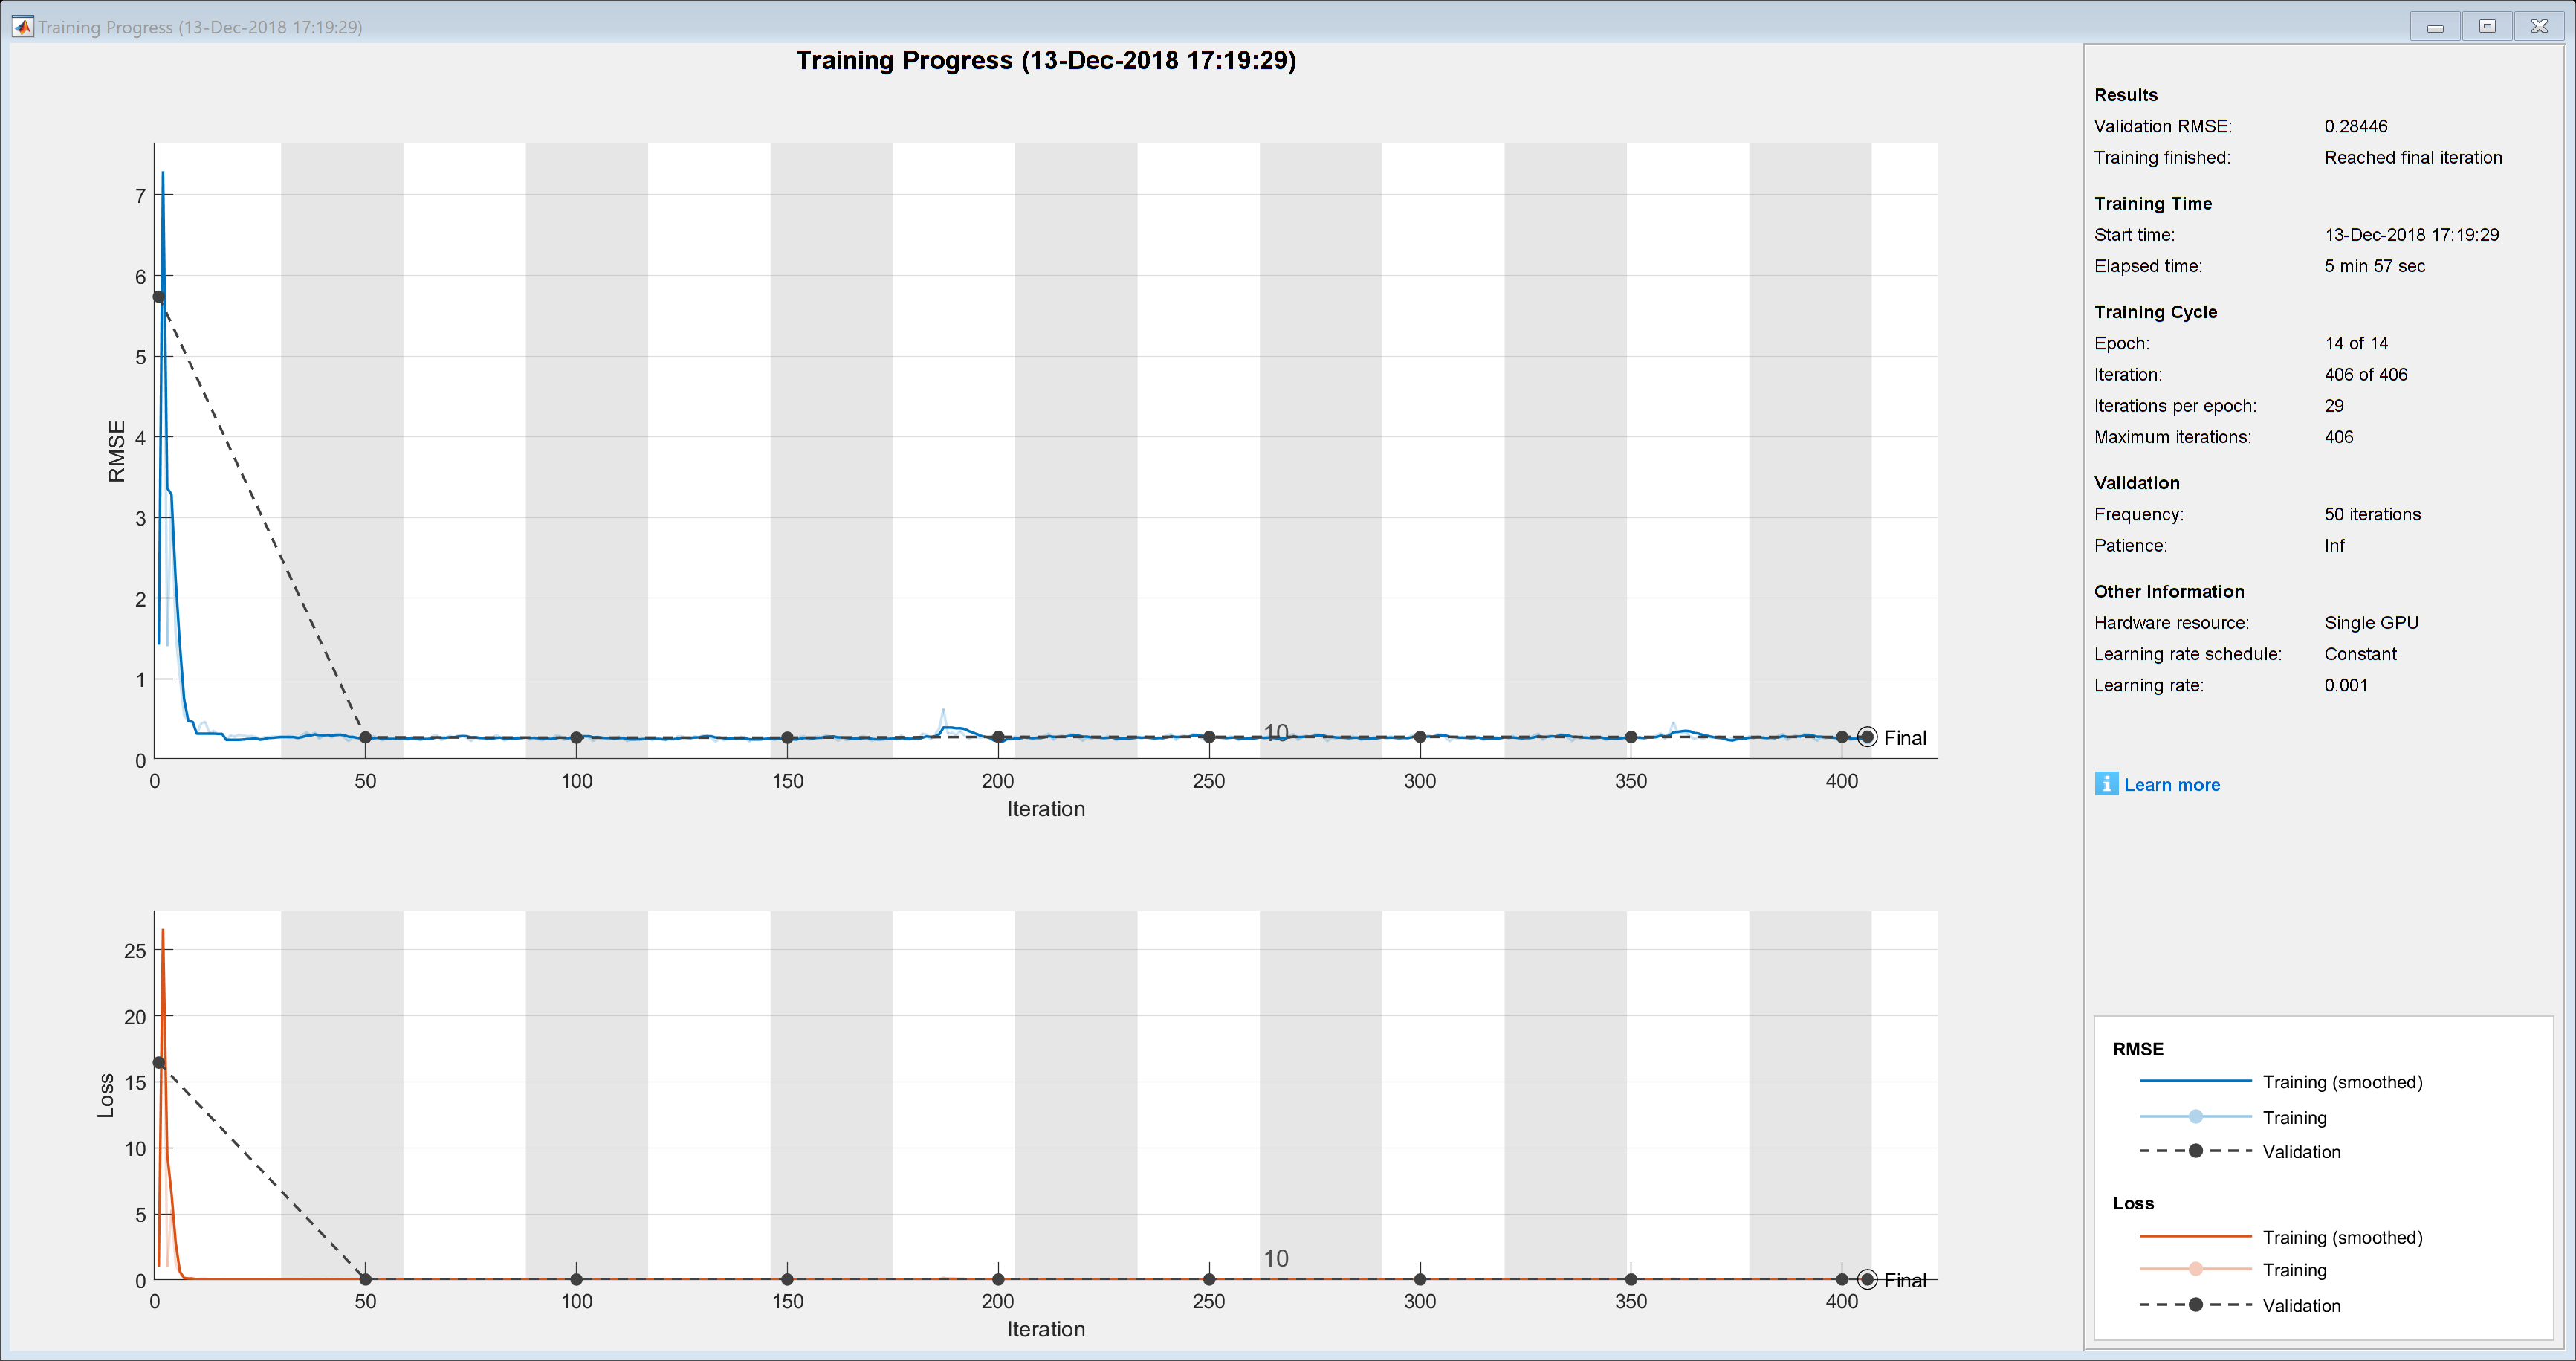

Initializing image normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         1.42 |         5.74 |       1.0140 |      16.4546 |          0.0010 |
|       2 |          50 |       00:00:51 |         0.27 |         0.28 |       0.0365 |       0.0383 |          0.0010 |
|       4 |         100 |       00:01:33 |         0.27 |         0.27 |       0.0373 |       0.0372 |          0.0010 |
|       6 |         150 |       00:02:16 |         0.24 |         0.27 |       0.0280 |       0.0370 |          0.0010 

hueCorrectionNetwork =   SeriesNetwork with properties:

    Layers: [24×1 nnet.cnn.layer.Layer]


hueCorrectionNetwork = trainNetwork(T, layers, opts)

Test an image

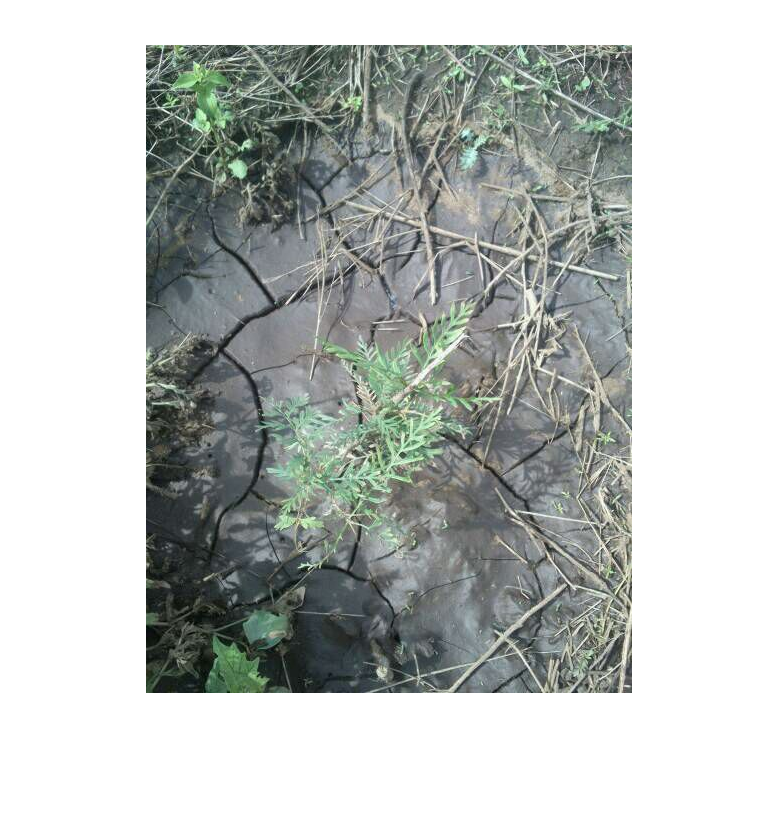

test = imread('140.jpg');
imshow(test);

test = imresize(test, [227 227]);

hsCorrection = predict(hueCorrectionNetwork, test)

hsCorrection = 1×2 single row vector
    0.0223    0.0375


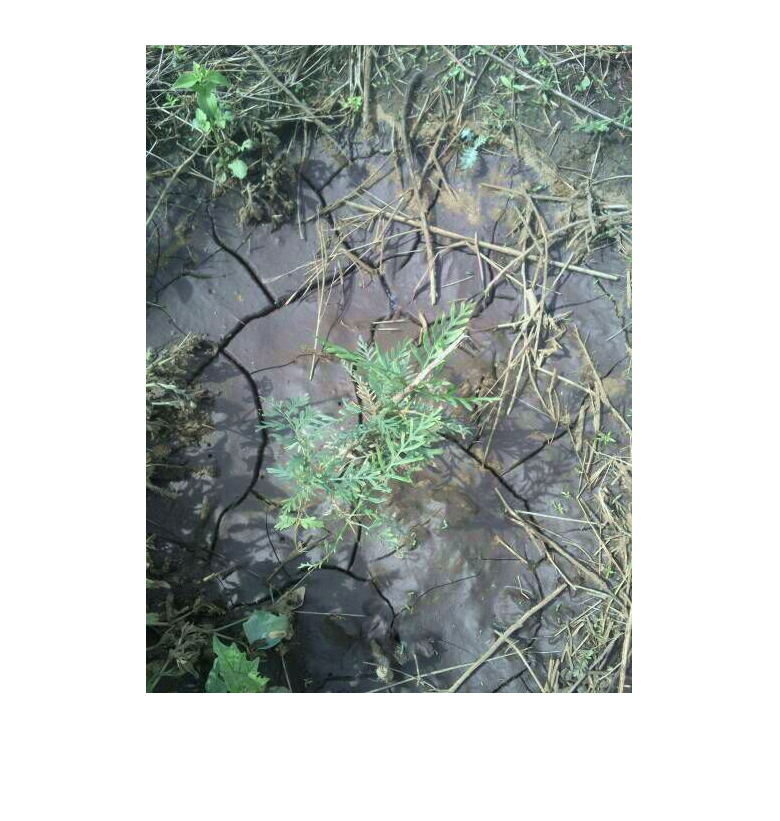

test = imread('140.jpg');
 hsvTest = rgb2hsv(test);
 hsvTest(:,:,1) =  hsvTest(:,:,1) + hsCorrection(1,1);
 hsvTest(:,:,2) =  hsvTest(:,:,2) + hsCorrection(1,2);

 rgbImage = hsv2rgb(hsvTest);
 imshow(rgbImage);

 imwrite(rgbImage,'140Corrected.tif','tif');
 
 
 

 

Save the network

 save('hueCorrectionNetwork.mat','hueCorrectionNetwork');